% Parameter values
xi = 0.0001;
c = 1;
beta = 3;
gamma = 1;
epsilon = 0.5;
alpha_i = 0.01;
alpha_s = 0.2;

% Set up parameter dictionary
par_keys = ["xi" "c" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
par_values = [xi c beta gamma epsilon alpha_i alpha_s];
par_dictionary = dictionary(par_keys, par_values)


par_dictionary =

  dictionary (string ⟼ double) with 7 entries:

    "xi"      ⟼ 1.0000e-04
    "c"       ⟼ 1
    "beta"    ⟼ 3
    "gamma"   ⟼ 1
    "epsilon" ⟼ 0.5000
    "alpha_i" ⟼ 0.0100
    "alpha_s" ⟼ 0.2000



# Plot relaxation oscillation in I(t)

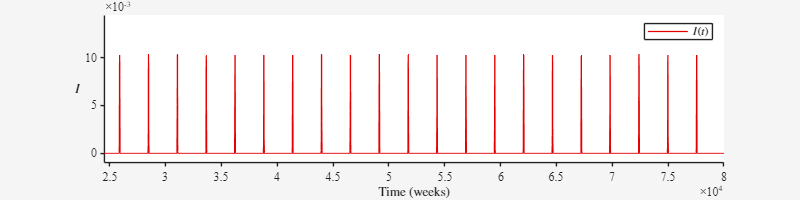

% Ode settings
tmax = 80000;
tspan = linspace(0, tmax, tmax+1);
i0 = 1e-2;
x0 = [1 - i0; i0; 0];
options = odeset("RelTol", 1e-13, "AbsTol", 1e-32);

% Solve the ODE
odefun = @(t,x) slow_fast_model(t, x, par_dictionary);
sol = ode89(odefun, tspan, x0, options);
x_time_series = deval(sol, linspace(0,tmax,tmax+1));
I_time_series = x_time_series(2,:);

% Choose a subset of the time series for plotting
tmin = 24500;
I_plot_data = I_time_series(tmin:end);
t_plot_data = tspan(tmin:end);

fig = figure("Position", [0 0 800 200]);
axis = axes(fig);
plot(t_plot_data, I_plot_data, "DisplayName", "$I(t)$", "Color", [0.9 0 0], "LineWidth", 1);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("$I$", "Interpreter", "latex", "Rotation", 0)
legend("Interpreter", "latex");
box(axis, "off");
axis.XAxis.TickLength = [0.005 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0.005 0];
axis.YAxis.FontName = "Times New Roman";
axis.LineWidth = 0.33;
set(axis, "TickDir", "out");

% Add axis padding
ylen = max(I_plot_data);
ypad = ylen * 0.1;
xlim([tmin, tmax]);
ylim([-ypad, ylen + ypad*4]);

theme(fig, "light");

exportgraphics(fig, "relaxation_oscillation.pdf", "Resolution", 300);

# Plot relaxation oscillation in all three variables

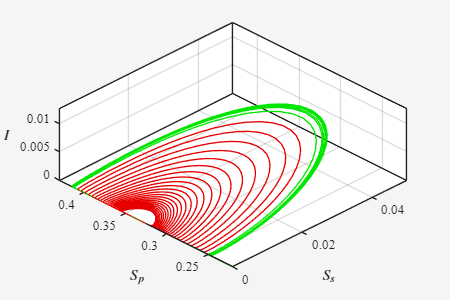

fig = figure("Position", [0 0 450 300]);
axis = axes(fig);
hold on;

% ___ Plot first solution ___

% Ode settings
tmax = 40000;
tspan = linspace(0, tmax, tmax+1);
i0 = 1e-2;
x0 = get_chadi_model_EE(par_dictionary) .* (1 + 8e-1);
options = odeset("RelTol", 1e-13, "AbsTol", 1e-32);

% Solve the ODE
odefun = @(t,x) slow_fast_model(t, x, par_dictionary);
sol = ode89(odefun, tspan, x0, options);
x_time_series = deval(sol, linspace(0,tmax,tmax+1));
Sp_time_series = x_time_series(1,:);
I_time_series = x_time_series(2,:);
Ss_time_series = x_time_series(3,:);

plot3(Ss_time_series, Sp_time_series, I_time_series, "Color", [0 0.9 0], "LineWidth", 1);

% ___ Plot second solution ___

% Ode settings
tmax = 30000;
tspan = linspace(0, tmax, tmax+1);
x0 = get_chadi_model_EE(par_dictionary) .* (1 + 5e-2);
options = odeset("RelTol", 1e-13, "AbsTol", 1e-32);

% Solve the ODE
odefun = @(t,x) slow_fast_model(t, x, par_dictionary);
sol = ode89(odefun, tspan, x0, options);
x_time_series = deval(sol, linspace(0,tmax,tmax+1));
Sp_time_series = x_time_series(1,:);
I_time_series = x_time_series(2,:);
Ss_time_series = x_time_series(3,:);

plot3(Ss_time_series, Sp_time_series, I_time_series, "Color", [0.9 0 0], "LineWidth", 1);

% Plot settings

xlabel("$S_s$", "Interpreter", "latex", "Rotation", 0);
ylabel("$S_p$", "Interpreter", "latex", "Rotation", 0);
zlabel("$I\quad$", "Interpreter", "latex", "Rotation", 0);

xlim([0 0.05]);
ylim([0.22 0.43]);
zlim([0 1.25e-2]);

axis.XAxis.FontName = "Times New Roman";
axis.YAxis.FontName = "Times New Roman";
axis.ZAxis.FontName = "Times New Roman";
set(axis, "TickDir", "out");

theme(fig, "light");
view(-45, 60);
grid on;
box on;
axis.LineWidth = 0.33;

exportgraphics(fig, "relaxation_oscillation_3D.pdf", "Resolution", 300);

function dx_dt = slow_fast_model(t, x, par_dictionary)
    xi = par_dictionary("xi");
    c = par_dictionary("c");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = c*xi - beta*Sp*I - xi*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + xi + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (xi + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end

% Returns the location of the endeimc equilibrium analytically using the
% equations in the Supplemental Material of Saad-Roy et al. (2023)
function x_star = get_chadi_model_EE(par_dictionary)
    Lambda = par_dictionary("xi")*par_dictionary("c");
    mu = par_dictionary("xi");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    A2 = -epsilon*beta*(mu + alpha_i);
    A1 = Lambda*epsilon*beta + epsilon*gamma*mu - (mu + gamma + alpha_i)/beta * (beta*(alpha_s + mu) + epsilon*beta*mu);
    A0 = Lambda*(alpha_s + mu) - (mu + gamma + alpha_i)/beta * mu*(alpha_s + mu);

    I_star = (-A1 - sqrt(A1^2 - 4*A0*A2)) / (2*A2);
    Ss_star = gamma*I_star / (epsilon*beta*I_star + alpha_s + mu);
    Sp_star = (mu + gamma + alpha_i)/beta - epsilon*Ss_star;

    x_star = [Sp_star; I_star; Ss_star];
end